## response(sys, ref)

Finds the response of the given system to the given reference/input signal. These can be given as tf-objects, symbolics or just the name of the response-type.

clear; s = tf('s'); syms t;
sys = (s+2)/(s^3+2*s^2+3*s+2)

sys =
 
          s + 2
  ---------------------
  s^3 + 2 s^2 + 3 s + 2
 
Continuous-time transfer function.



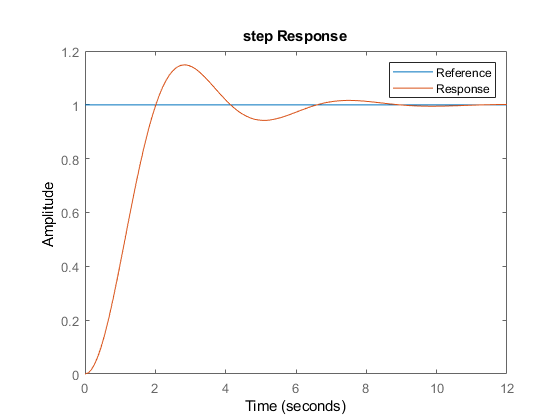

ans =
 
            s + 2
  -------------------------
  s^4 + 2 s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.



ELAB.response(sys, 'step')

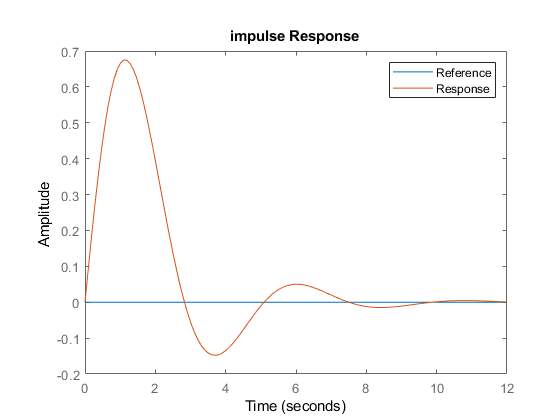

ans =
 
          s + 2
  ---------------------
  s^3 + 2 s^2 + 3 s + 2
 
Continuous-time transfer function.



ELAB.response(sys, 'impulse')

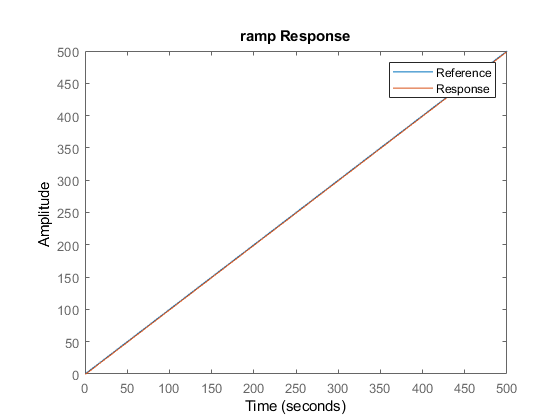

ans =
 
             s + 2
  ---------------------------
  s^5 + 2 s^4 + 3 s^3 + 2 s^2
 
Continuous-time transfer function.



ELAB.response(sys, 'ramp')

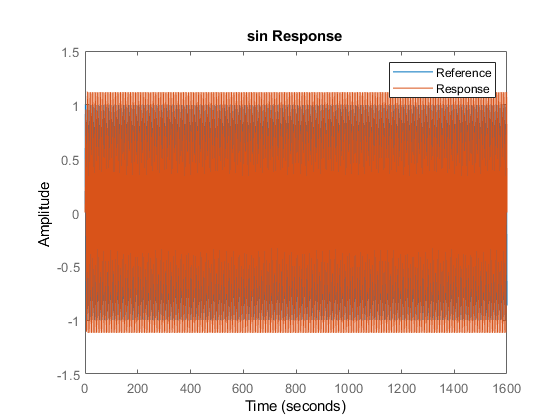

ans =
 
                  s + 2
  -------------------------------------
  s^5 + 2 s^4 + 4 s^3 + 4 s^2 + 3 s + 2
 
Continuous-time transfer function.



ELAB.response(sys, 'sin')

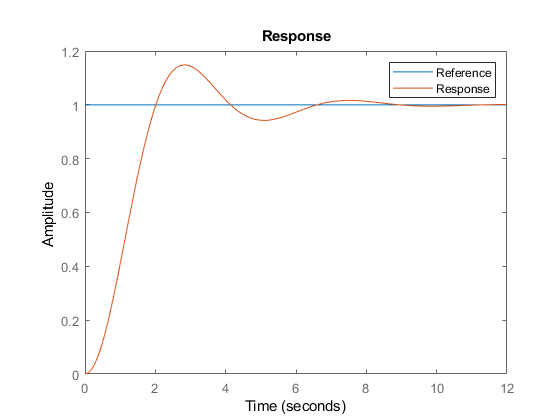

ans =
 
            s + 2
  -------------------------
  s^4 + 2 s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.



ELAB.response(sys, 1/s)

Converting symbolic to tf-object.


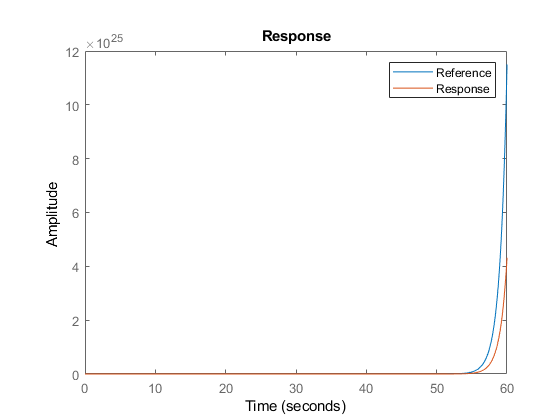

ans =
 
           s + 2
  -----------------------
  s^4 + s^3 + s^2 - s - 2
 
Continuous-time transfer function.



ELAB.response(sys, exp(t))